clear
Fs=5000000

Fs = 5000000

windowSize=2^20 ;
window=hamming(windowSize);
overlap=windowSize/2;
nfft=2^20;
N=Fs*5;%10sec (max 10)
centerfreq=2403000000;

## sample 1 (no ble)

% f=fopen('04_aug_sample3','rb'); % Opens the file to read as binary data.
% y=fread(f,'uint');
% % IQ data is a stream of I-Q-I-Q... points.
% yReal=y(1:2:end); % Set the real points
% yImag=y(2:2:end); % Set the imaginary points
% yc=yReal+j*yImag; % Create the actual complex samples
%yc=iqFile2complex('10_aug_sample3',N)
yc=wavFile2complex('04-May-2023 111841.556 2403.000MHz.wav',N);

duration=length(yc)/Fs %test sample length

duration = 5

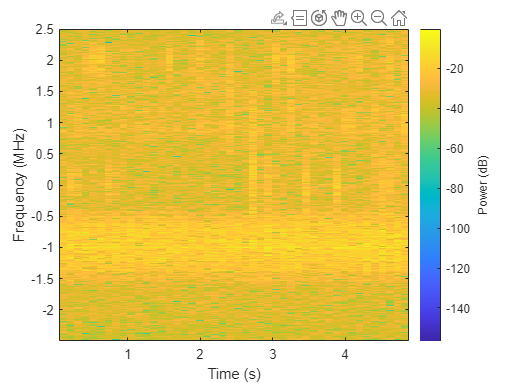

spectrogram(yc(1:N), window,overlap,nfft,Fs, 'centered','power','yaxis');%signal,window,noverlap,nfft,Fs

% [s, f, t]=spectrogram(yc(1:N), window,overlap,nfft,Fs,'centered', 'yaxis');%signal,window,noverlap,nfft,Fs

% spectrogram_dB = 10 * log10(abs(s));
% figure;
% imagesc(t, f, spectrogram_dB);
% axis xy;  % Flip the y-axis to align with the conventional spectrogram orientation
% xlabel('Time (s)');
% ylabel('Frequency (Hz)');
% title('Spectrogram');
% colorbar;  % Add a color bar for the magnitude scale
% colormap;
% uicontrol('Visible','off')


## sample 2 (BLE)

clear
Fs=5000000

Fs = 5000000

windowSize=2^20 ;
window=hamming(windowSize);
overlap=windowSize/2;
nfft=2^20;
N=Fs*5;%10sec (max 10)
centerfreq=2403000000;


f2=fopen('04_aug_sample2','rb'); % Opens the file to read as binary data.
y2=fread(f2,'uint'); 
% IQ data is a stream of I-Q-I-Q... points.
yReal2=y2(1:2:end); % Set the real points
yImag2=y2(2:2:end); % Set the imaginary points
yc2=yReal2+j*yImag2; % Create the actual complex samples

%spectrogram(yc2(1:N), window,overlap,nfft,Fs,'centered', 'yaxis');%signal,window,noverlap,nfft,Fs
[s2, f2, t2]=spectrogram(yc2(1:N), window,overlap,nfft,Fs,'centered', 'yaxis');%signal,window,noverlap,nfft,Fs

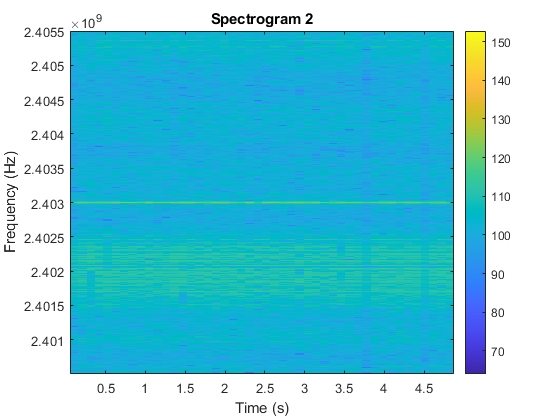

spectrogram_dB2 = 10 * log10(abs(s2));
figure;
imagesc(t2, f2+centerfreq, spectrogram_dB2);
axis xy;  % Flip the y-axis to align with the conventional spectrogram orientation
xlabel('Time (s)');
ylabel('Frequency (Hz)');
zlabel('Power/freq (dB/Hz)')
title('Spectrogram 2');
colorbar;  % Add a color bar for the magnitude scale
colormap;
uicontrol('Visible','off')